### Question 1

Implement fixed-point iteration. Your signature should be

function p = fp(g, p0, maxits)

a) g : x → (x + 2/x)/2

g = @(x) (x + 2/x)/2;
fp(g, 1, 3)

ans = 1.4142

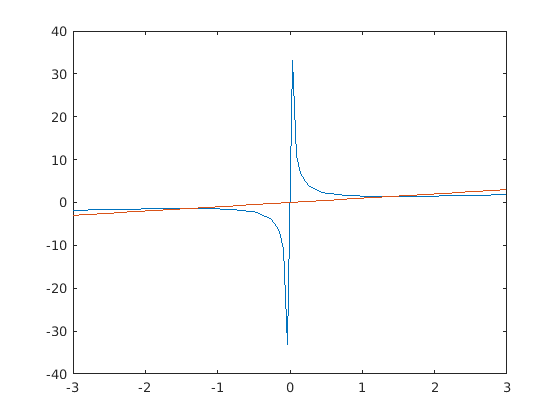

x1 = linspace(-3,3,100);
y1 = 0;
for i = 1:length(x1)
    y1(i) = g(x1(i));
end
y2 = x1;

plot(x1,y1,x1,y2)

    i) Done, visually graphed.

    ii) if p0 is negative, such as -1, it will approach -sqrt2, if p0 is positive, such as 1, it will approach sqrt2. Maxits can be any value greater than 2 depending on how close p0 is to the actual value.

    iii)

b) g : x → cos(x)

g = @(x) cos(x);
fp(g, 1, 3)

ans = 0.6543

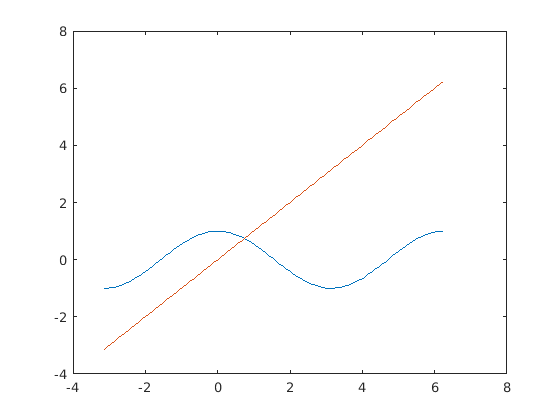

x1 = linspace(-3.14,6.24,100);
y1 = 0;
for i = 1:length(x1)
    y1(i) = g(x1(i));
end
y2 = x1;

plot(x1,y1,x1,y2)

c) g : x → 2x

g = @(x) 2 * x;
fp(g, 0, 30)

ans = 0

d) g :    x/2 when x != 0

            1 when x = 0

g = @(x) pwf(x);
fp(g, 1, 1000)

ans = 9.3326e-302

function p = fp(g, p0, maxits)
    p = g(p0);
    for i = 2:maxits
        p = g(p);
    end
end

function value = pwf(x)
    if x ~= 0
        value = x / 2;
    else
        value = 1;
    end
end